# Lab 5: Cross-Device OFDM Transmission

## [Part 2]

clear;
N = 64;
Ncp = 16;
fc = 915*1e6;
fs = 1e6;

pilot_bins = [-21 -7 7 21];
used_bins  = setdiff([-26:-1 1:26], pilot_bins);
idx = @(k) k + N/2 + 1;
N_samp = 100;
pilot_bits = randi([0 1], numel(pilot_bins), 1);
pilot = pskmod(pilot_bits, 2);

### training symbols generation

sts_bins = [-24 -20 -16 -12 -8 -4 4 8 12 16 20 24];
sts_signs = [ 1 -1  1 -1 -1  1 -1 -1  1  1  1  1];  
    
% Map to FFT bins
X_sts = zeros(N,1);
for i = 1:numel(sts_bins)
    X_sts(idx(sts_bins(i))) = sts_signs(i) * (1+1j);
end
X_sts = X_sts * sqrt(13/6);
    
x_sts_64 = ifft(ifftshift(X_sts), N);
x_sts_16 = x_sts_64(1:Ncp);
x_sts = repmat(x_sts_16, 10, 1);

lts_bins = [-26:-1 1:26];
lts_signs = [ ...
1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1,  1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1, ...
1, -1, -1,  1,  1, -1,  1, -1,  1, -1, -1, -1, -1, -1,  1,  1, -1, -1,  1, -1,  1, -1,  1,  1,  1,  1];
    
X_lts = zeros(N,1);
for i = 1:numel(lts_bins)
    X_lts(idx(lts_bins(i))) = lts_signs(i);
end
    
x_lts = ifft(ifftshift(X_lts), N);


## (1)

data_bits = randi([0 1], numel(used_bins)*log2(16), N_samp);
x_tx = OFDM(data_bits, N_samp, pilot, idx(pilot_bins), idx(used_bins), N, Ncp, 16);

data_symb =    0.3162 + 0.9487i  -0.9487 - 0.3162i  -0.3162 - 0.9487i  -0.3162 + 0.3162i  -0.3162 + 0.3162i  -0.3162 - 0.9487i  -0.3162 - 0.3162i   0.9487 + 0.9487i   0.3162 + 0.9487i  -0.9487 - 0.9487i   0.9487 + 0.3162i  -0.3162 + 0.3162i   0.9487 + 0.3162i   0.9487 - 0.3162i   0.9487 + 0.9487i  -0.3162 + 0.3162i   0.9487 - 0.3162i   0.3162 - 0.3162i  -0.3162 - 0.9487i  -0.3162 + 0.9487i  -0.3162 - 0.9487i  -0.3162 - 0.3162i  -0.9487 + 0.9487i  -0.3162 + 0.3162i   0.9487 - 0.3162i  -0.3162 + 0.3162i   0.9487 - 0.9487i  -0.9487 - 0.3162i   0.9487 + 0.3162i   0.9487 + 0.3162i   0.3162 + 0.9487i   0.9487 - 0.3162i   0.9487 + 0.9487i   0.3162 + 0.3162i   0.9487 + 0.9487i   0.3162 + 0.3162i  -0.9487 - 0.9487i   0.3162 - 0.9487i  -0.9487 - 0.9487i  -0.9487 + 0.9487i   0.3162 - 0.3162i  -0.9487 - 0.9487i   0.9487 - 0.3162i  -0.3162 + 0.3162i  -0.3162 + 0.3162i   0.9487 - 0.9487i   0.3162 + 0.9487i   0.3162 + 0.9487i   0.3162 - 0.3162i   0.9487 - 0.3162i
  -0.3162 + 0.9487i  -0.9487 - 0.3162

[x_tx_TS, lts_normalization_factor] = add_TS(x_tx, x_sts, x_lts);
x_tx_ext = [zeros(100,1); x_tx_TS; zeros(100,1)];

[x_rx1, x_rx2, idx_frame1_start, idx_frame2_start] = USRP_channel_multi(x_tx_ext, x_lts, 1);

Detected strong frame at ii=5, P=0.00207 > THR=0.0001
TX peak after backoff: 0.363 | median RX1 peak: 0.000
max |zL1| = 0.6171, max |zL2| = 0.0389


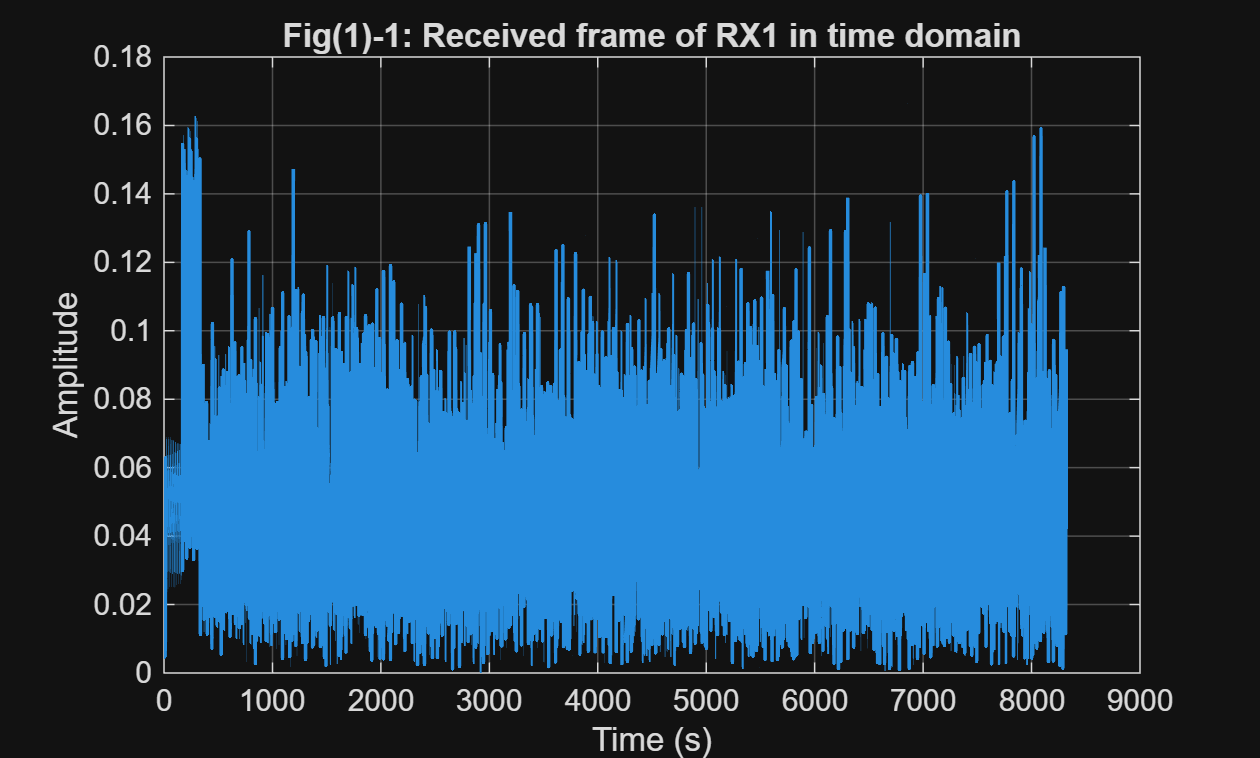


figure;
t_axis = (0:numel(x_tx_TS)-1)/fs;
plot(1:length(x_rx1), abs(x_rx1), 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Fig(1)-1: Received frame of RX1 in time domain');

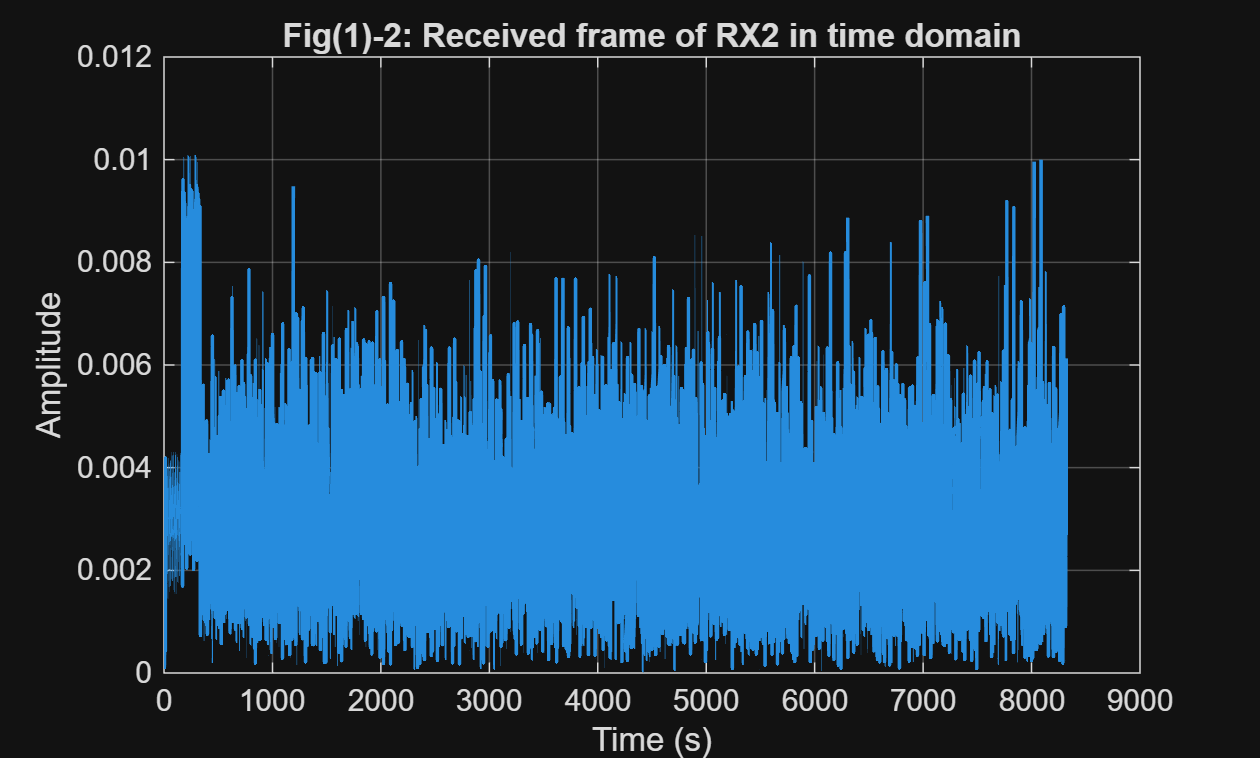

figure;
plot(1:length(x_rx2), abs(x_rx2), 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Fig(1)-2: Received frame of RX2 in time domain');

## (2) Starting index of the two RX signals

fprintf("The starting index of frame1 is %d.", idx_frame1_start);

The starting index of frame1 is 72400.

fprintf("The starting index of frame2 is %d.", idx_frame2_start);

The starting index of frame2 is 72400.

if idx_frame1_start == idx_frame2_start
    fprintf("The two indices are the same.");
else
    fprintf("The two indices are not the same.");
end

The two indices are the same.

## (3) SNR

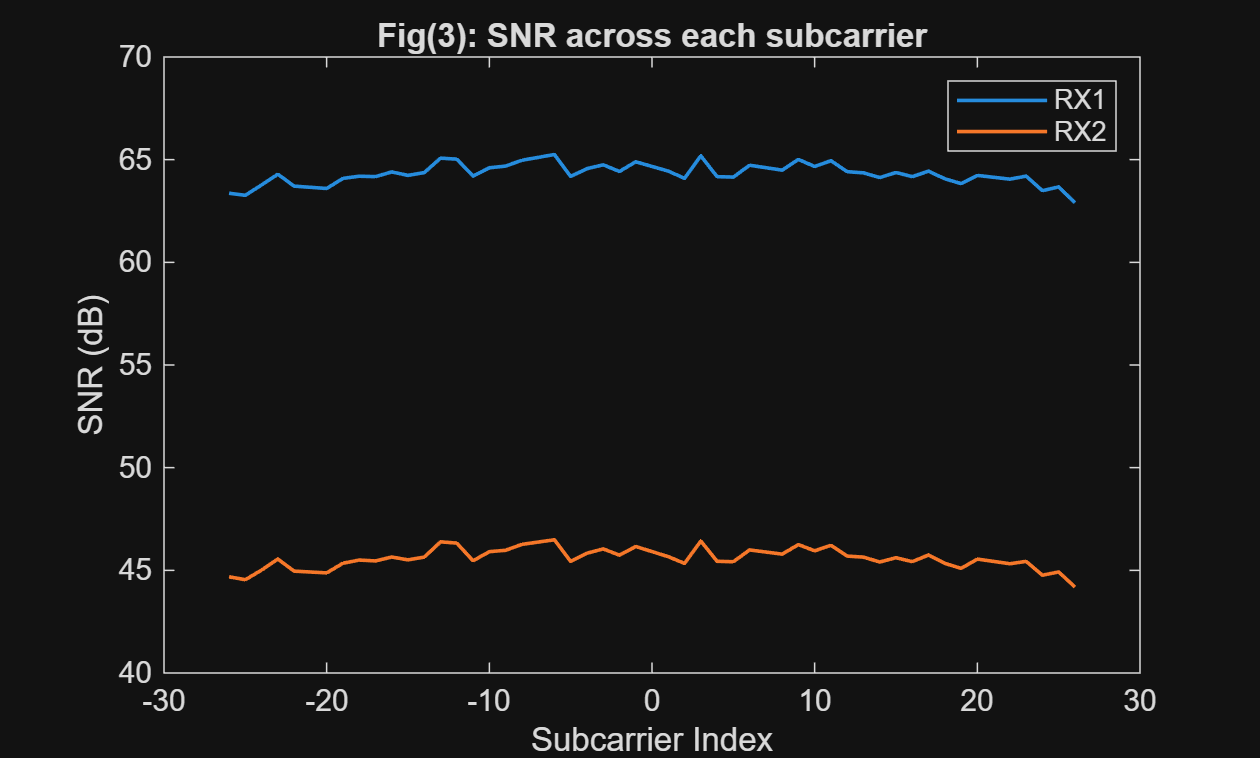

[noise1, noise2] = noise_detection(1);

x_rx_CFO_1 = CFO_est(x_rx1, fs);
x_rx_CFO_2 = CFO_est(x_rx2, fs);


H_CFO_1 = channel_est(x_rx_CFO_1(161:320), x_lts, lts_normalization_factor);
H_CFO_2 = channel_est(x_rx_CFO_2(161:320), x_lts, lts_normalization_factor);

% ==== Parameters ====
symb_len  = N + Ncp;                  
frame_len = symb_len * N_samp;        


frame_symb_1 = x_rx_CFO_1(321 : 320 + frame_len);  
frame_symb_2 = x_rx_CFO_2(321 : 320 + frame_len);

frame_mat1 = reshape(frame_symb_1(:), symb_len, N_samp); 
frame_mat2 = reshape(frame_symb_2(:), symb_len, N_samp);  

% ==== Remove CP ====
data_mat1 = frame_mat1(Ncp+1:end, :);   % 64 x N_samp
data_mat2 = frame_mat2(Ncp+1:end, :);   % 64 x N_samp

% ==== FFT for all symbols, both antennas ====
Y1 = fftshift(fft(data_mat1, [], 1), 1);   % 64 x N_samp
Y2 = fftshift(fft(data_mat2, [], 1), 1);   % 64 x N_samp

% ==== Per-subcarrier equalization (H_CFO_* are 64x1) ====
Y1_eq = Y1 ./ H_CFO_1;   % implicit expansion: 64 x N_samp
Y2_eq = Y2 ./ H_CFO_2;   % 64 x N_samp

% ==== Pilot-based common phase correction ====
% Pilot tones on equalized symbols
pilot_est1 = Y1_eq(idx(pilot_bins), :);       % Npilot x N_samp
pilot_est2 = Y2_eq(idx(pilot_bins), :);       % Npilot x N_samp

% pilot is Npilot x 1
corr1 = mean(pilot_est1 ./ pilot, 1);         % 1 x N_samp (per-symbol)
corr2 = mean(pilot_est2 ./ pilot, 1);         % 1 x N_samp

% Apply per-symbol phase/gain correction on used bins
X1_eq_pilot = Y1_eq(idx(used_bins), :) ./ corr1;   % 48 x N_samp
X2_eq_pilot = Y2_eq(idx(used_bins), :) ./ corr2;   % 48 x N_samp

% ---- Per-subcarrier noise variance after equalization ----
H1_used = H_CFO_1(idx(used_bins));      % 48 x 1
H2_used = H_CFO_2(idx(used_bins));      % 48 x 1

% ---- Signal+noise power from equalized, pilot-corrected symbols ----
X1 = X1_eq_pilot(:,:);                  % 48 x N_samp  (antenna 1)
X2 = X2_eq_pilot(:,:);                  % 48 x N_samp  (antenna 2)

sigpow1 = mean(abs(X1).^2, 2);           % 48 x 1
sigpow2 = mean(abs(X2).^2, 2);           % 48 x 1

Y1_used = Y1(idx(used_bins), :);
Y2_used = Y2(idx(used_bins), :);

sigpow1 = mean(abs(Y1_used).^2, 2);
sigpow2 = mean(abs(Y2_used).^2, 2);

% sigpow1 = max(sigpow1 - noise1, 0);
% sigpow2 = max(sigpow2 - noise2, 0);

sigpow1 = max(sigpow1, 0);
sigpow2 = max(sigpow2, 0);

% sigpow1 = mean(abs(x_rx1) .^2, 2);
% sigpow2 = mean(abs(x_rx2) .^2, 2);

% ---- SNR per subcarrier (linear and dB) ----
snr1_lin = sigpow1 ./ noise1;
snr2_lin = sigpow2 ./ noise2;

snr1_lin = max(snr1_lin, eps);           % clamp to avoid negative / log issues
snr2_lin = max(snr2_lin, eps);

snr1_db = 10*log10(snr1_lin);            % 48 x 1, antenna 1
snr2_db = 10*log10(snr2_lin);            % 48 x 1, antenna 2

figure;
plot(used_bins, snr1_db, 'LineWidth', 1.2); hold on;
plot(used_bins, snr2_db, 'LineWidth', 1.2);
xlabel("Subcarrier Index");
ylabel("SNR (dB)");
legend("RX1", "RX2");
title("Fig(3): SNR across each subcarrier");

The trend of the two SNR curves over different subcarriers are similar, but they differ by a constant magnitude.

(We think that it might be due to the different gain configuration between the 2 RX channels)

## (4) Constellations

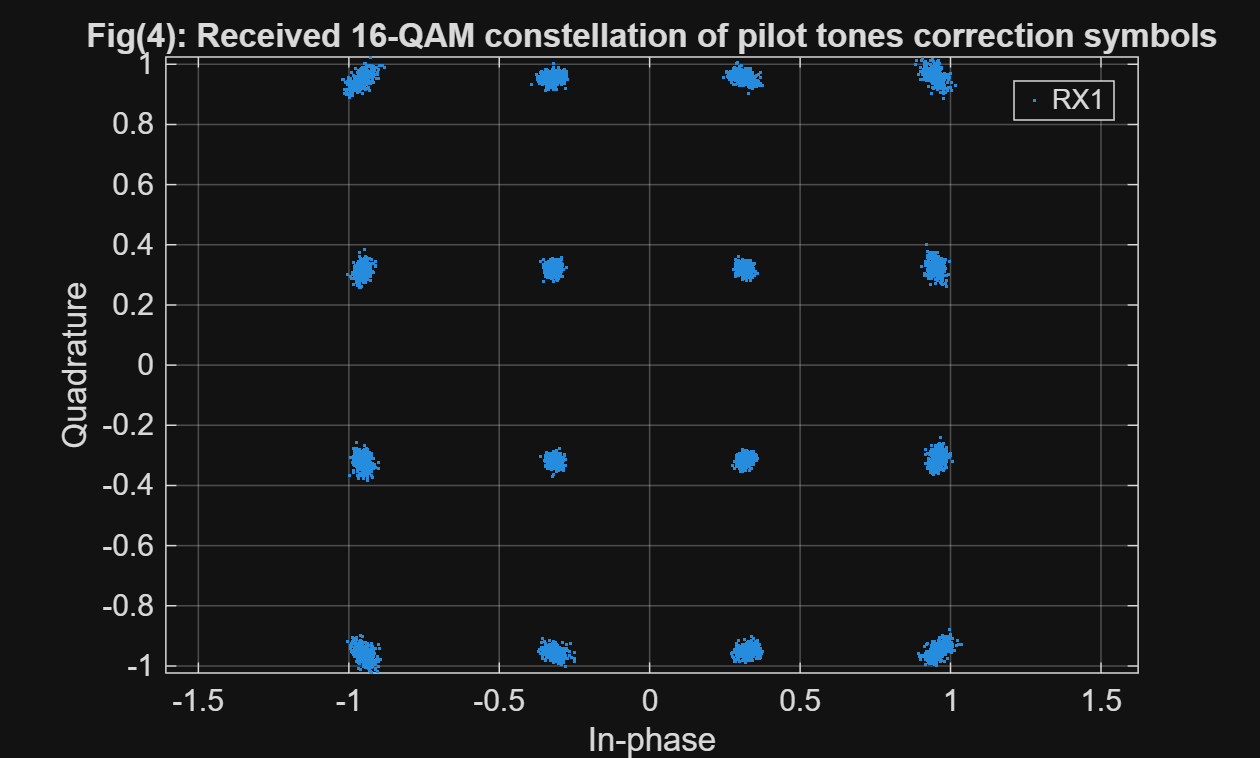

figure;
plot(real(X1(:)), imag(X1(:)), '.', 'MarkerSize', 2); hold on;
% plot(real(X2(:)), imag(X2(:)), '.', 'MarkerSize', 2);
grid on; axis equal;
legend('RX1');
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(4): Received 16-QAM constellation of pilot tones correction symbols'));

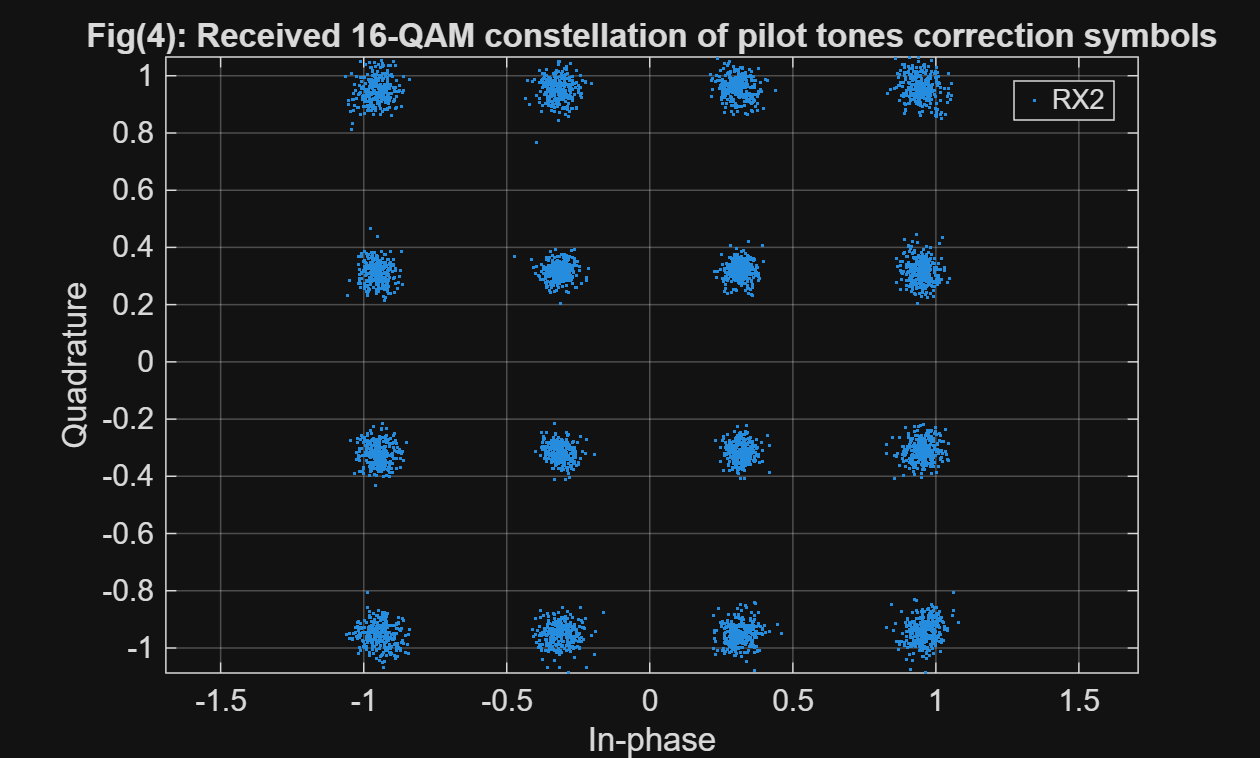

figure;
% plot(real(X1(:)), imag(X1(:)), '.', 'MarkerSize', 2); 
plot(real(X2(:)), imag(X2(:)), '.', 'MarkerSize', 2);
grid on; axis equal;
legend('RX2');
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(4): Received 16-QAM constellation of pilot tones correction symbols'));

The constellation of the two RX channels are both corrected to near the original transmitted 16-QAM symbols.

## (5) MRC SNR

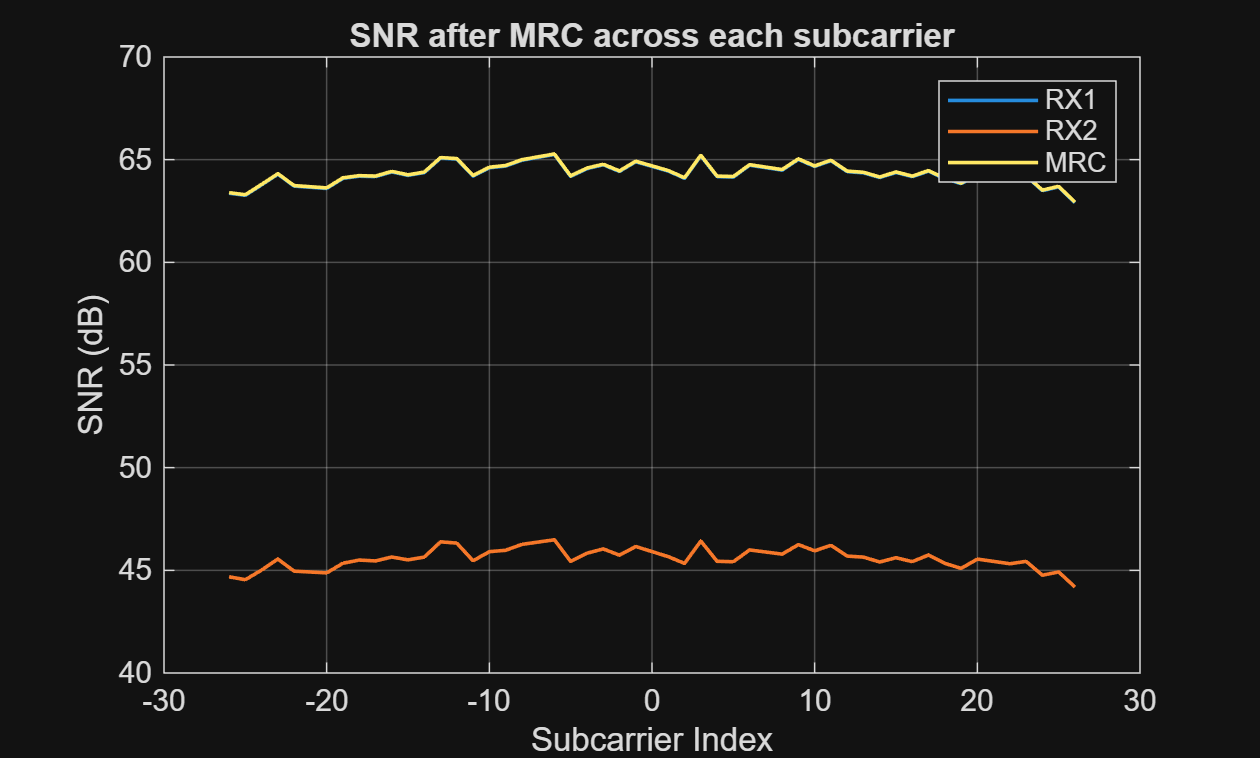

% --- MRC weights per subcarrier ---
w1 = conj(H_CFO_1);     % 48x1
w2 = conj(H_CFO_2);     % 48x1

w1_used = conj(H1_used);
w2_used = conj(H2_used);

% expand weights across symbols
w1_mat = repmat(w1, 1, N_samp);   % 48 x N_samp
w2_mat = repmat(w2, 1, N_samp);   % 48 x N_samp

w1_mat_used = repmat(w1_used, 1, N_samp);   % 48 x N_samp
w2_mat_used = repmat(w2_used, 1, N_samp);   % 48 x N_samp

Y_mrc_used = w1_mat_used .* Y1_used + w2_mat_used .* Y2_used; 

% --- MRC combined frequency-domain signal and effective channel ---
Y_mrc   = w1_mat .* Y1 + w2_mat .* Y2;               % 48 x N_samp
H_eff   = w1 .* H_CFO_1 + w2 .* H_CFO_2;                       % 48 x 1
H_eff_mat = repmat(H_eff, 1, N_samp);                          % 48 x N_samp

% --- Equalize after MRC (for constellation, demod, etc.) ---
X_mrc = Y_mrc ./ H_eff_mat;   % 48 x N_samp, combined constellation

% pilot correction
X_pilot_mrc = X_mrc(idx(pilot_bins), :);        
corr_mrc = mean(X_pilot_mrc ./ pilot, 1);   % 1 x N_samp

X_mrc_corr = X_mrc ./ corr_mrc;
X_mrc_data = X_mrc_corr(idx(used_bins), :);

sigpow_mrc = mean(abs(X_mrc_data).^2, 2);

sigpow_mrc = mean(abs(Y_mrc_used).^2, 2);
% noise_eff = (mnoise1 + noise2)/2;
% sigpow_mrc = max(sigpow_mrc - noise_eff, 0);
noise_eff = abs(w1_used).^2 * noise1 + abs(w2_used).^2 * noise2;    % 48x1

snr_mrc_lin = max(sigpow_mrc./noise_eff, eps);
snr_mrc_db = 10 * log10(snr_mrc_lin);  % Convert SNR from linear to dB
snr_mrc_ref_db = 10 * log10(snr1_lin+snr2_lin); % reference 

figure;
plot(used_bins, snr1_db, 'LineWidth', 1.2); hold on;
plot(used_bins, snr2_db, 'LineWidth', 1.2);
plot(used_bins, snr_mrc_db, 'LineWidth', 1.2);
% plot(used_bins, snr_mrc_ref_db, '--', 'LineWidth', 1.2);
legend('RX1', 'RX2', 'MRC');
xlabel("Subcarrier Index");
ylabel("SNR (dB)");
title("SNR after MRC across each subcarrier");
grid on;

We also plot the reference MRC (SNR1+SNR2). We could observe that our experimental SNR for MRC aligns well with the ideal SNR for MRC.

## (6) MRC constellations

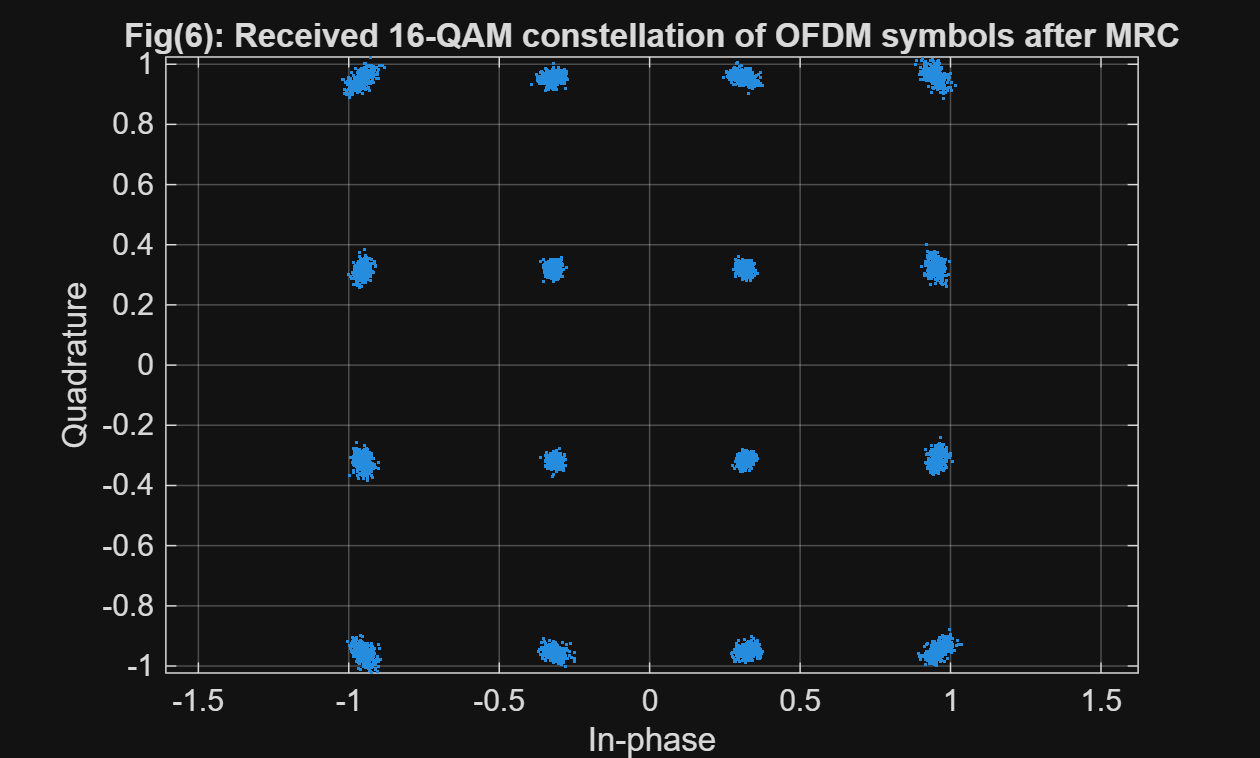

figure;
plot(real(X_mrc_data(:)), imag(X_mrc_data(:)), '.', 'MarkerSize', 2); 
grid on; axis equal;
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(6): Received 16-QAM constellation of OFDM symbols after MRC'));

We could see that after MRC, the constellation is more concentrated around the ideal 16-QAM symbols.

functions:

function [radio_Tx, radio_Rx] = USRP_init_multi(rx_length, fs)
% USRP init for N200/N210/USRP2 with 10 MS/s host rate
    platform  = "N200/N210/USRP2";
    address   = '192.168.10.2';
    fc = 915*1e6;     % center frequency
    txGain_dB = 5;         % tune as needed (avoid clipping)
    rxGain_dB = 20;
    interfactor = round(100/fs);
    decimfactor = round(20/fs);

    radio_Tx = comm.SDRuTransmitter( ...
        'Platform',          platform, ...
        'IPAddress',         address, ...
        'CenterFrequency',   fc, ...
        'Gain',              txGain_dB, ...
        'MasterClockRate',   100e6, ...
        'InterpolationFactor', interfactor);

    radio_Rx = comm.SDRuReceiver( ...
        'Platform',          "B210", ...
        'SerialNum',         "310C576", ...
        'CenterFrequency',   fc, ...
        'SamplesPerFrame',   rx_length, ...
        'ChannelMapping',    [1,2], ...
        'Gain',              [20 5], ...
        'MasterClockRate',   20e6, ...
        'DecimationFactor',  decimfactor, ...
        'OutputDataType',    'double');
end

function x_cp = OFDM(data_bits, N_samp, pilot, pilot_bins, used_bins, FFT_size, cp_size, qam)
    data_symb = qammod(data_bits, qam, 'gray', InputType='bit', UnitAveragePower=true)
    
    xcp_all = complex(zeros(FFT_size+cp_size, N_samp));
    
    for n = 1:N_samp
        % ----- 1) Build frequency-domain X for one OFDM symbol -----
        X = zeros(FFT_size,1);
    
        % pilots (BPSK ±1)
        X(pilot_bins) = pilot;
    
        % data (take this symbol's mapped constellation)
        X(used_bins) = data_symb(:, n);
    
        % ----- 2) IFFT -> time domain -----
        x = ifft(ifftshift(X));                % 64 samples
    
        % ----- 3) Add cyclic prefix -----
        xcp_all(:, n) = [x(end-cp_size+1:end); x];
    end
    x_cp = xcp_all(:);
end

function [x_ts, alpha_lts] = add_TS(x_tx, x_sts, x_lts)

    CP_LTS = 32;

    % --- Compute average powers ---
    P_tx  = mean(abs(x_tx).^2);
    P_lts = mean(abs(x_lts).^2);

    % alpha_lts = sqrt(P_tx / max(P_lts, eps));
    alpha_lts = max(abs(x_tx)) / max(abs(x_lts));

    x_lts_norm = alpha_lts * x_lts;

    x_lts_field = [x_lts_norm(end-CP_LTS+1:end); x_lts_norm; x_lts_norm];
    x_ts = [x_sts; x_lts_field; x_tx];
end

function H_LTS = channel_est(frame_LTS, x_lts, normalization_factor)
    X_LTS = fftshift(fft(x_lts));
    frame_lts1 = frame_LTS(32+1:32+64);
    frame_lts2 = frame_LTS(end-64+1:end);
    Y_LTS1 = fftshift(fft(frame_lts1));
    Y_LTS2 = fftshift(fft(frame_lts2));
    H_LTS = (Y_LTS1+Y_LTS2)/(2*normalization_factor) .* X_LTS;
end

function BER = ber_cal(x, y)
    BER = mean(x ~= y);
end

function x_rx = USRP_channel_new(x_tx_CFO, x_lts, x_sts, fs)
    Fs = 1e6; % host-side rate (matches Interp/Decim=10 for 100 MHz) 
    Ns_frame = numel(x_tx_CFO); 
    % ---- Build one TX packet per iteration: frame + guard zeros (fixed length) ---- 
    guard_len = 0; % 80 us of silence @ 10 MS/s (tune 400–2000 as needed) 
    tx_one = [x_tx_CFO(:); zeros(guard_len,1)]; % complex column 
    Ltx = numel(tx_one); % ---- Backoff to avoid clipping at DAC ---- % 
    
    rx_length = 2.0*Ltx; 
    [radio_Tx, radio_Rx] = USRP_init(rx_length, fs); 
    l = rx_length; 
    n = 2000;
    % buffer = complex(zeros(n+30,rx_length)) ;
    THR_POW = 1e-4;
    found = false;
    det_idx = NaN;
    max_scan = n+50;
    success = false;
    % Transmit and receive for 50 frames 
    while ~success
        buffer = complex(zeros(n+30,rx_length)) ;

        for k = 1:3
            step(radio_Rx);
        end
        for ii = 1 : max_scan 
            tunderrun = radio_Tx(tx_one); 
            [rcvdSignal, ~, toverflow] = step(radio_Rx); % buffer(ii,:) = real(rcvdSignal.' ); 
            buffer(ii,:) = rcvdSignal.' ; 
            received_power = mean(abs(rcvdSignal).^2);
            if ~found && received_power>THR_POW
                found = true;
                det_idx = ii;
                fprintf('Detected strong frame at ii=%d, P=%.3g > THR=%.3g\n', ii, received_power, THR_POW);
                break
            end
            if found
                break
            end
        end
        
        
        if found
            for jj = 1:30
                [rcvdSignal, ~, toverflow] = step(radio_Rx); %#ok<ASGLU>
                buffer(det_idx+jj,:) = rcvdSignal.';
            end
            last_idx = det_idx + 30;
        else
            % If not found, still capture some extra for inspection
            fprintf('No strong frame detected (THR=%.3g). Capturing 30 extra frames anyway.\n', THR_POW);
            for jj = 1:30
                [rcvdSignal, ~, toverflow] = step(radio_Rx); %#ok<ASGLU>
                buffer(max_scan+jj,:) = rcvdSignal.';
            end
            last_idx = max_scan + 30;
        end
        
        
        % ---- Quick health checks ---- 
        rx_peaks = max(abs(buffer(1:n,:)),[],2); 
        fprintf('TX peak after backoff: %.3f | median RX peak: %.3f\n', max(abs(tx_one)), median(rx_peaks));
        % fprintf('TX peak after backoff: %.3f | median RX peak: %.3f\n', max(abs(tx_one)), median(rx_peaks));
        
        % ---- Pick one received frame and plot with region markers (no correlation yet) ----
        buffer_squeezed = reshape(buffer.', 1, []).';
        Ncp_LTS = 32;        % LTS CP length (samples)
        ST_len = 16;        % short symbol length
        sts_len = 10*ST_len; % 10 repeats of 16
        LT_len = 64;        % one LTS body
        N = 64;
        extracted_piece = buffer_squeezed;
        x_received = extracted_piece(:).';         % ensure row vector
        
        % x_received = frame;
        
        % ---- LTS matched filter (time-reversed, conjugated) ----
        hL = conj(fliplr(x_lts));           % MF kernel
        yL_full = conv(x_received, hL, 'full');
        yL = yL_full(1:length(x_received));   % align length
        
        % ---- Two-peak comb: pick two adjacent LTS (LTS1 & LTS2) ----
        combL = zeros(1, 2*N);             % length = 128
        combL(1) = 1;
        combL(N+1) = 1;                          % second peak N samples later
        
        % Convolve comb with |yL| to score aligned double-LTS patterns
        zL_full = conv(yL, combL, 'full');
        zL= zL_full(numel(combL):end);        % align to x_received

        success = true;
        fprintf("max zl = %.4f", max(abs(zL)));
    end
    release(radio_Tx) 
    release(radio_Rx) 
    % ---- Peak detection & indices ----
    [~, zL_max_index] = max(abs(zL));   
    idx_lts1  = zL_max_index;
    idx_lts_cp = idx_lts1 - Ncp_LTS;            % CP starts 32 samples before LTS1
    idx_sts = idx_lts_cp - sts_len;          % STS region start
    idx_data = idx_lts_cp + (Ncp_LTS + 2*N);  % start of data symbols
    
    % Bound to valid range
    clip = @(x) max(1, min(x, numel(x_received)));
    idx_lts1 = clip(idx_lts1);
    idx_lts_cp = clip(idx_lts_cp);
    idx_sts = clip(idx_sts);
    idx_data = clip(idx_data);
    
    idx_frame_start = idx_sts-100;
    
    idx_sts_one_frame = idx_sts - idx_frame_start + 1;
    idx_lts1_one_frame = idx_lts1 - idx_frame_start + 1;
    idx_lts_cp_one_frame = idx_lts_cp - idx_frame_start + 1;
    idx_data_one_frame = idx_data - idx_frame_start + 1;
    

    t_us = (0:length(x_received)-1)/Fs * 1e6;

    x_received_one_frame = x_received(idx_frame_start:idx_frame_start+8520-1); % 8520 for 100 frames
    x_rx = x_received_one_frame(101: numel(x_received_one_frame)-100);
    x_rx = x_rx.';

    t_us = (0:numel(x_received_one_frame)-1)/Fs * 1e6;
    
end

%{
function [x_rx1, x_rx2] = USRP_channel_multi(x_tx_CFO, x_lts, fs)
    Fs = 1e6; % host-side rate (matches Interp/Decim=10 for 100 MHz) 
    Ns_frame = numel(x_tx_CFO); 
    % ---- Build one TX packet per iteration: frame + guard zeros (fixed length) ---- 
    guard_len = 0; % 80 us of silence @ 10 MS/s (tune 400–2000 as needed) 
    tx_one = [x_tx_CFO(:); zeros(guard_len,1)]; % complex column 
    Ltx = numel(tx_one); % ---- Backoff to avoid clipping at DAC ---- % 
    
    n = 2000;
    rx_length = 2.0*Ltx; 
    [radio_Tx, radio_Rx] = USRP_init_multi(rx_length, fs); 
    THR_POW = 1e-4;
    found = false;
    det_idx = NaN;
    max_scan = n+50;

    for ii = 1 : max_scan 
        tunderrun = radio_Tx(tx_one); 
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        received_power = sum(mean(abs(rcvdSignal).^2));
        if ~found && received_power>THR_POW
            found = true;
            det_idx = ii;
            fprintf('Detected strong frame at ii=%d, P=%.3g > THR=%.3g\n', ii, received_power, THR_POW);
            break
        end
        if found
            break
        end
    end

    x_rx1 = rcvdSignal(:, 1);
    x_rx2 = rcvdSignal(:, 2);
end
%}

function [x_rx1, x_rx2, idx_frame_start1, idx_frame_start2] = USRP_channel_multi(x_tx_CFO, x_lts, fs)
    Fs = 1e6;              % host-side rate
    Ns_frame = numel(x_tx_CFO);

    % ---- Build one TX packet per iteration ----
    guard_len = 0;
    tx_one = [x_tx_CFO(:); zeros(guard_len,1)];   % column
    Ltx   = numel(tx_one);

    rx_length = 2.0 * Ltx;
    [radio_Tx, radio_Rx] = USRP_init_multi(rx_length, fs);

    n        = 2000;
    THR_POW  = 1e-4;
    max_scan = n + 50;
    success  = false;

    % We'll buffer both antennas separately:
    % buffer1(frame_idx, sample_idx) = ch1
    % buffer2(frame_idx, sample_idx) = ch2

    while ~success
        buffer1 = complex(zeros(n+30, rx_length));
        buffer2 = complex(zeros(n+30, rx_length));

        % warm up RX
        for k = 1:3
            step(radio_Rx);
        end

        found   = false;
        det_idx = NaN;

        % ----- Scan for strong frame (using antenna 1 power) -----
        for ii = 1:max_scan
            tunderrun = radio_Tx(tx_one);
            [rcvdSignal, ~, toverflow] = step(radio_Rx);  % size: [rx_length x 2]

            % store both channels
            buffer1(ii,:) = rcvdSignal(:,1).';
            buffer2(ii,:) = rcvdSignal(:,2).';

            received_power = mean(abs(rcvdSignal(:,1)).^2);  % use ch1 to detect
            if ~found && received_power > THR_POW
                found   = true;
                det_idx = ii;
                fprintf('Detected strong frame at ii=%d, P=%.3g > THR=%.3g\n', ...
                        ii, received_power, THR_POW);
                break
            end
        end

        % ----- Capture 30 more frames after detection -----
        if found
            for jj = 1:30
                [rcvdSignal, ~, toverflow] = step(radio_Rx);
                buffer1(det_idx+jj,:) = rcvdSignal(:,1).';
                buffer2(det_idx+jj,:) = rcvdSignal(:,2).';
            end
        else
            fprintf('No strong frame detected (THR=%.3g). Capturing 30 extra frames anyway.\n', THR_POW);
            for jj = 1:30
                [rcvdSignal, ~, toverflow] = step(radio_Rx);
                buffer1(max_scan+jj,:) = rcvdSignal(:,1).';
                buffer2(max_scan+jj,:) = rcvdSignal(:,2).';
            end
        end

        % ---- Quick health checks (antenna 1) ----
        rx_peaks = max(abs(buffer1(1:n,:)),[],2);
        fprintf('TX peak after backoff: %.3f | median RX1 peak: %.3f\n', ...
                max(abs(tx_one)), median(rx_peaks));

        % ---- Flatten buffers per antenna ----
        buffer_squeezed1 = reshape(buffer1.', 1, []).';
        buffer_squeezed2 = reshape(buffer2.', 1, []).';

        x_received1 = buffer_squeezed1(:).';
        x_received2 = buffer_squeezed2(:).';

        % ---- LTS MF + two-peak comb per antenna ----
        N        = 64;
        Ncp_LTS  = 32;
        ST_len   = 16;
        sts_len  = 10*ST_len;
        % LT_len = 64; % not directly needed

        hL = conj(fliplr(x_lts));  % MF kernel
        combL = zeros(1, 2*N);
        combL(1)   = 1;
        combL(N+1) = 1;

        % === Antenna 1 ===
        yL1_full = conv(x_received1, hL, 'full');
        yL1      = yL1_full(1:length(x_received1));
        zL1_full = conv(yL1, combL, 'full');
        zL1      = zL1_full(numel(combL):end);

        % === Antenna 2 ===
        yL2_full = conv(x_received2, hL, 'full');
        yL2      = yL2_full(1:length(x_received2));
        zL2_full = conv(yL2, combL, 'full');
        zL2      = zL2_full(numel(combL):end);

        % For now, accept this capture (you can add thresholds on max|zL1|, max|zL2|)
        success = true;
        fprintf("max |zL1| = %.4f, max |zL2| = %.4f\n", ...
                max(abs(zL1)), max(abs(zL2)));
    end

    % Done with hardware
    release(radio_Tx);
    release(radio_Rx);

    % ---- Peak detection & indices per antenna ----
    [~, zL1_max_index] = max(abs(zL1));
    [~, zL2_max_index] = max(abs(zL2));

    idx_lts1_1  = zL1_max_index;
    idx_lts_cp1 = idx_lts1_1 - Ncp_LTS;
    idx_sts1    = idx_lts_cp1 - sts_len;
    idx_data1   = idx_lts_cp1 + (Ncp_LTS + 2*N);

    idx_lts1_2  = zL2_max_index;
    idx_lts_cp2 = idx_lts1_2 - Ncp_LTS;
    idx_sts2    = idx_lts_cp2 - sts_len;
    idx_data2   = idx_lts_cp2 + (Ncp_LTS + 2*N);

    % bound to valid range
    clip1 = @(x) max(1, min(x, numel(x_received1)));
    idx_lts1_1  = clip1(idx_lts1_1);
    idx_lts_cp1 = clip1(idx_lts_cp1);
    idx_sts1    = clip1(idx_sts1);
    idx_data1   = clip1(idx_data1);

    clip2 = @(x) max(1, min(x, numel(x_received2)));
    idx_lts1_2  = clip2(idx_lts1_2);
    idx_lts_cp2 = clip2(idx_lts_cp2);
    idx_sts2    = clip2(idx_sts2);
    idx_data2   = clip2(idx_data2);

    % ---- Extract one frame per antenna ----
    pad = 100;
    frame_len = 8520;  % your chosen window

    % Antenna 1
    idx_frame_start1 = idx_sts1 - pad;
    idx_frame_start1 = clip1(idx_frame_start1);
    idx_frame_end1   = idx_frame_start1 + frame_len - 1;
    idx_frame_end1   = clip1(idx_frame_end1);

    x_received_one_frame1 = x_received1(idx_frame_start1:idx_frame_end1);
    x_rx1 = x_received_one_frame1(pad+1 : end-pad).';   % column

    % Antenna 2
    idx_frame_start2 = idx_sts2 - pad;
    idx_frame_start2 = clip2(idx_frame_start2);
    idx_frame_end2   = idx_frame_start2 + frame_len - 1;
    idx_frame_end2   = clip2(idx_frame_end2);

    x_received_one_frame2 = x_received2(idx_frame_start2:idx_frame_end2);
    x_rx2 = x_received_one_frame2(pad+1 : end-pad).';   % column
end


function [last_peak, status] = matched_filter(pattern, frame, L)
    mf = conj(flipud(pattern));  
    sync_s = abs(conv(frame, mf, 'same'));
    P_avg = cumsum(abs(frame).^2) ./ (1:length(frame)).' + 0.01; % This added constant avoids the peak value at the beginning when P_avg is very low
    peak_pos = (sync_s./P_avg > L);
    last_peak = find(peak_pos, 1, 'last');
    status = (sum(peak_pos) == 2);
end


function [noise1, noise2] = noise_detection(fs)
    test_tx = zeros(10000, 1);
    rx_length = numel(test_tx);
    [radio_Tx, radio_Rx] = USRP_init_multi(rx_length, fs);

    tunderrun = radio_Tx(test_tx); 
    [rcvdSignal, ~, toverflow] = step(radio_Rx);

    rx1 = rcvdSignal(:,1);
    rx2 = rcvdSignal(:,2);

    noise1 = mean(abs(rx1).^2);
    noise2 = mean(abs(rx2).^2);
end

function x_rx_CFO = CFO_est(x_rx, fs)
    L_lts = 64;
    s = 160+L_lts/2;
    lts1 = x_rx(s+1:s+L_lts);
    lts2 = x_rx(s+L_lts+1:s+L_lts*2);
    
    p_lts = sum(conj(lts1) .* lts2);
    phi_lts = angle(p_lts);
    df_est_lts = phi_lts*fs/(2*pi*L_lts);
    
    CFO_corr_16 = exp(-1j*2*pi*(0:numel(x_rx)-1)*df_est_lts/fs).';
    x_rx_CFO = x_rx .* CFO_corr_16;
end
